# Obtain Solution and Lagrange Multipliers

Solve a simple linear program and examine the solution and the Lagrange multipliers.

Use the objective function


$$f(x) = -5x_1-4x_2-6x_3.$$


clear all
f = [-5; -4; -6];

Use the linear inequality constraints


$$ x_1 - x_2 + x_3 \le 20$$



$$ 3x_1 + 2x_2 + 4x_3 \le 42$$



$$ 3x_1 + 2x_2 \le 30.$$


A =  [1 -1  1
      3  2  4
      3  2  0];
b = [20;42;30];

Constrain all variables to be positive:


$$x_1\ge 0$$



$$x_2\ge 0$$



$$x_3\ge 0.$$


lb = zeros(3,1);

Set `Aeq` and `beq` to `[]`, indicating that there are no linear equality constraints.

Aeq = [];
beq = [];

Call `linprog`, obtaining the Lagrange multipliers.

[x,fval,exitflag,output,lambda] = linprog(f,A,b,Aeq,beq,lb);


Optimal solution found.



Examine the solution and Lagrange multipliers.

x,lambda.ineqlin,lambda.lower

x =          0
   15.0000
    3.0000


ans =          0
    1.5000
    0.5000


ans =     1.0000
         0
         0


`Interior-point method`

A = [1	-1	1	1	0	0
     3	 2	4	0	1	0
     3	 2	0	0	0	1];
 b = [20;42;30];
 c = [-5;-4;-6;0;0;0];
  initial_guess= [1 1 1 19 33 25]';
x = karmarkar(A,b,c,initial_guess);
x(:,end)

ans =     0.0000
   15.0000
    3.0000
   32.0000
    0.0000
    0.0000


A 2-D example


$$min -3x_1-2x_2\\
2x_1+x_2 \le 100\\
x_1+x_2 \le 80\\
x_1,x_2 \ge 0$$


A =[2,1,1,0;1,1,0,1];
b = [100;80];
c = [-3;-2;0;0];
initial_guess= [10 10 70 60 ]';
x = karmarkar(A,b,c,initial_guess);

x(:,end)

ans =    20.0000
   60.0000
    0.0000
    0.0000


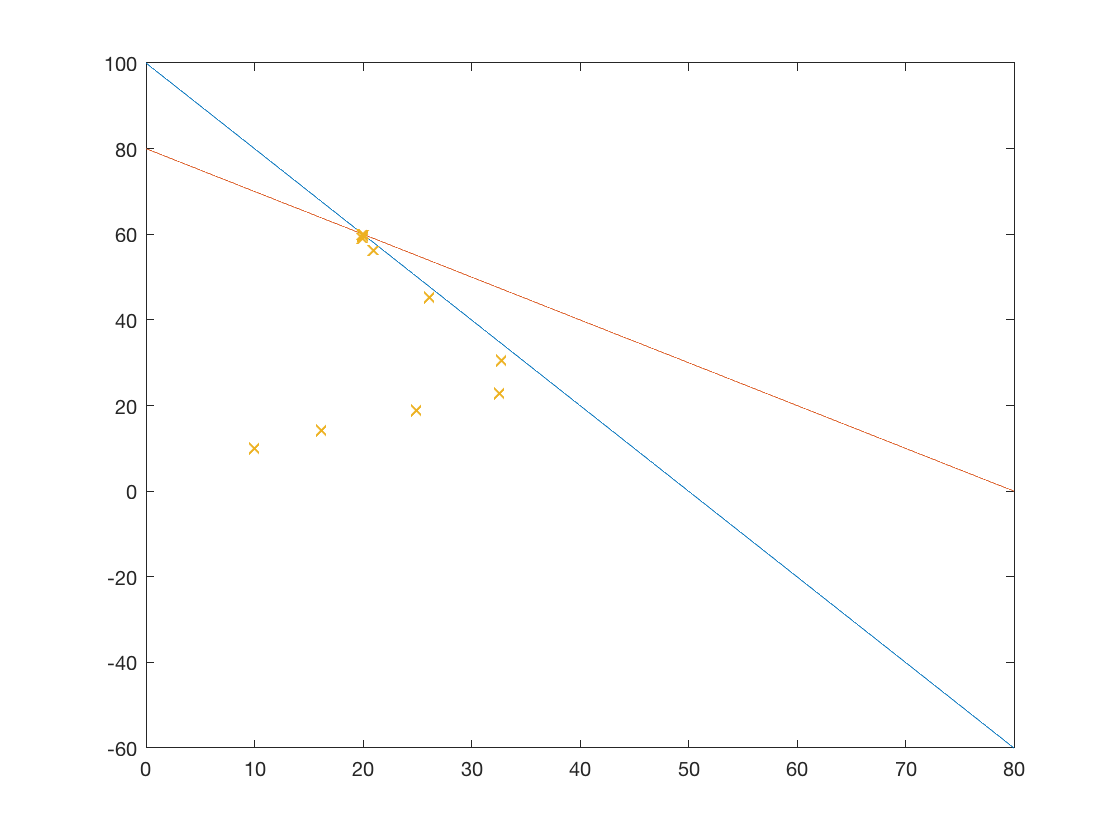

figure (2)
x1 = 0:0.1:80;
x2 = 0:0.1:80;
y1 = 100 -2*x1;
y2 = 80 -x2;
plot(x1,y1,x2,y2);
hold on
plot(x(1,:),x(2,:),'x');